#  ENME462 Studio 8 Root Locus Basics

by Xie Zheng

Section 0101 W 1:00PM - 2:50PM;

Github: [https://github.com/XieGT/Control_Studios](https://github.com/XieGT/Control_Studios)

## Root Locus

- It is a plot of the path of the roots of the characteristic equation (closed-loop system poles) as one system parameter is varied.

- Number of branches is the same as the number of closed-loop poles.

- It is symmetric about the real axis.

Steps for sketching a root locus

- Write the characteristic equation, locate the open loop poles & zeros.

- Locate the segments of the real axis ( it lies in a section of the real axis to the **left** of an** odd** number of real poles and zeros)

- Find the asymptotes( center: $\sigma_a=\left(\sum_{k=1}^{n}{-p_k}-\sum_{k=1}^{m}{-z_i}\right)/(n-m)$, with angle $\phi_{a}=\frac{2h+1}{n-m}\times180^o, \quad h=0,1,2...,n-m-1$) 

- Determine where the root locus crosses the imaginary axis (using the Routh-Hurwitz criterion).

- Determine the break-away / break-in point(s) on the real axis($\frac{dK}{ds}=0, \quad \frac{d^2K}{ds^2}=0$) 

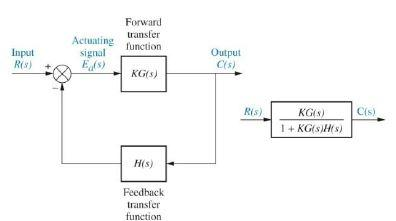

## Assignment

Given the feedback system shown below.

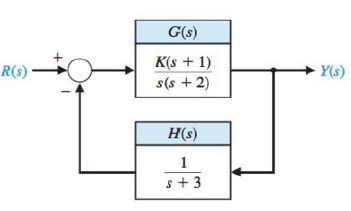

a) Determine the characteristic equation for the closed loop system

syms K s
G = (s+1)/(s*(s+2));
H = 1/(s+3);
GH = G*H

$$GH = \frac{s+1}{s\,\left(s+2\right)\,\left(s+3\right)}$$

CharEq = s*(s+2)*(s+3)+ K*(s+1) == 0

$$CharEq = K\,\left(s+1\right)+s\,\left(s+2\right)\,\left(s+3\right)=0$$

b) Determine the number of asymptotes and their angles

GH_zeros = [-1]

GH_zeros = -1

GH_poles = [0, -2, -3]

GH_poles =      0    -2    -3


n = length(GH_poles)

n = 3

m = length(GH_zeros)

m = 1

sigma_a = (sum(GH_poles) - sum(GH_zeros)) / (n-m)

sigma_a = -2

h = 0:n-m-1

h =      0     1


phi_a = (2.*h +1)./(n-m).*180

phi_a =     90   270


c) Sketch the RL

GH_c = zpk(GH_zeros, GH_poles, 1)


GH_c =
 
      (s+1)
  -------------
  s (s+2) (s+3)
 
Continuous-time zero/pole/gain model.



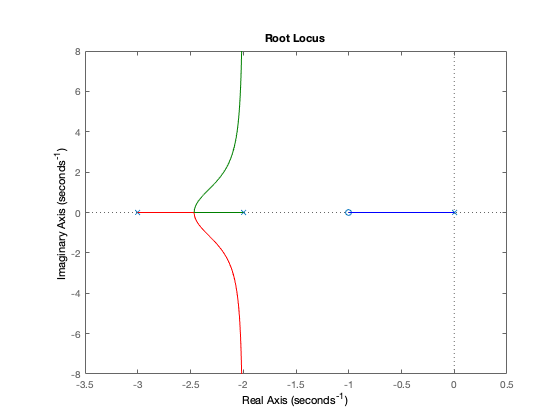

rlocus(GH_c)

d) Determine the break-away point

K_d = -1/(GH)

$$K\_d = -\frac{s\,\left(s+2\right)\,\left(s+3\right)}{s+1}$$

dK = diff(K_d);
dK = simplify(dK);
s = roots([1, 4, 5, 3])

s =   -2.4656 + 0.0000i
  -0.7672 + 0.7926i
  -0.7672 - 0.7926i


e) Determine the range of K for which the system is stable

CharEq= collect(CharEq)

$$CharEq = s^{3}+5\,s^{2}+\left(K+6\right)\,s+K=0$$

s3  = [1, K+6]

$$s3 = \left(\begin{array}{cc} 1 & K+6 \end{array}\right)$$

s2 = [5, K]

$$s2 = \left(\begin{array}{cc} 5 & K \end{array}\right)$$

s1 = [(5*(K+6)-K)/5, 0]

$$s1 = \left(\begin{array}{cc} \frac{4\,K}{5}+6 & 0 \end{array}\right)$$

s0 = [K ,0]

$$s0 = \left(\begin{array}{cc} K & 0 \end{array}\right)$$

RH_table = [s3;s2;s1;s0]

$$RH\_table = \left(\begin{array}{cc} 1 & K+6\\ 5 & K\\ \frac{4\,K}{5}+6 & 0\\ K & 0 \end{array}\right)$$